# Analysis of a 3D system

## Stable stationary point

Examine the system


$$\begin{array}{l}
d_t x=-x-\mathrm{arctg}\left(z\right),\\
d_t y=x-2y,\\
d_t z=y-3z\ldotp 
\end{array}$$


The only stationary point is $\overrightarrow{s_0 } =\left(x_0 ,y_0 ,z_0 \right)=\overrightarrow{0}$.

A = [-1, 0, -1;
    1, -2, 0;
    0, 1, -3];
x_up = pi/2;
y_up = pi/4;
z_up = pi/12;

Characteristic polynomial

char_p = -poly(A)

char_p =    -1.0000   -6.0000  -11.0000   -7.0000


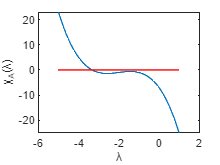

lam = linspace(-5, 1);

figure(1);
plot(lam, polyval(char_p, lam));
line([min(lam), max(lam)], [0, 0], 'Color', 'red');
xlabel('\lambda');
ylabel('\chi_A(\lambda)');

Eigenvalues

eig(A)

ans =   -1.3376 + 0.5623i
  -1.3376 - 0.5623i
  -3.3247 + 0.0000i


% roots(char_p)

Streamslice from some random points

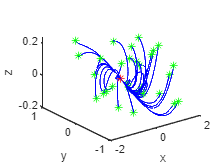

x_up = pi/2;
y_up = pi/4;
z_up = pi/12;

[x, y, z] = meshgrid(...
    linspace(-x_up, x_up, 101),...
    linspace(-y_up, y_up, 101),...
    linspace(-z_up, z_up, 101));

dx = -x - atan(z);
dy = -x - 2*y;
dz = y - 3*z;

Nstart = 30;
rng('default');
sx = (rand(Nstart, 1) - .5) * 2*x_up;
sy = (rand(Nstart, 1) - .5) * 2*y_up;
sz = (rand(Nstart, 1) - .5) * 2*z_up;

figure(2);
streamline(stream3(x, y, z, dx, dy, dz, sx, sy, sz));
view(3);
xlabel('x');
ylabel('y');
zlabel('z');
hold on;
plot3(0, 0, 0, '*r');
plot3(sx, sy, sz, '*g');
hold off;

## Unstable stationary point

Now consider a system


$$\begin{array}{l}
d_t x=-0\ldotp 01x-\mathrm{arctg}\left(z\right),\\
d_t y=x-0\ldotp 02y,\\
d_t z=y-3z,
\end{array}$$


with one stationary point $\overrightarrow{s_0 } =\left(x_0 ,y_0 ,z_0 \right)=\overrightarrow{0}$.

Use Runge-Kutta method to integrate the system.

First, redefine the parameters

A = [-.01, 0, -1;
    1, -.02, 0;
    0, 1, -3];
x_up = pi/.02;
y_up = pi/.0004;
z_up = pi/.0012;

rng('default');
Nstart = 10;
sx = normrnd(0, 10, Nstart, 1);
sy = normrnd(0, 10, Nstart, 1);
sz = normrnd(0, 10, Nstart, 1);

There are eigenvalues with positive real part, and therefore the stationary point $\overrightarrow{s_0 } =\left(x_0 ,y_0 ,z_0 \right)=\overrightarrow{0}$is unstable.

eig(A)

ans =    0.0374 + 0.5665i
   0.0374 - 0.5665i
  -3.1048 + 0.0000i


Now integrate the system

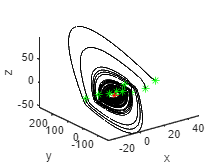

T = 200;
tau = .01;
tspan = 0:tau:T;
figure(3)
for k = 1 : Nstart
    [t, S] = ode45(@ode_system, tspan, [sx(k), sy(k), sz(k)]);
    tl = length(t);
    plot3(S(:, 1), S(:, 2), S(:, 3), '-k'); hold on;
%     plot3(S(round(tl/4):end, 1), S(round(tl/4):end, 2), S(round(tl/4):end, 3), '-k');
    hold on;
end
plot3(0, 0, 0, '*r');
plot3(sx, sy, sz, '*g');
hold off;
xlabel('x');
ylabel('y');
zlabel('z');

## Poincare Method

Define the starting point $S_0 =\left(0,\;20\ldotp 2,\;6\ldotp 7\right)$. Make two steps: in the direction of the second basis vector $\overrightarrow{v_2 } =\left(0,1,0\right)$ and in the direction of the third basis vector $\overrightarrow{v_3 } =\left(0,0,1\right)$.

S_0 = [0, 20.2, 6.7];
S_p = [S_0 + [0, 1, 0]; S_0 + [0, 0, 1]];

Initialize the matrix $A$of the linear operator and integrate the system starting from $S_p$ points.

A_p = zeros(2);

for k = 1 : 2
    [t, S] = ode45(@ode_system, tspan, S_p(k, :));
    tl = length(t);
    
    half_ind = find(S(:, 1) > 0, 1);
    S = S(half_ind:end, :);
    
    one_ind = find(S(:, 1) < 0, 1);
    A_p(:, k) = S(one_ind, 2:3) - S_0(2:3);
end

eig_vals = eig(A_p);
abs(eig_vals)

ans =     0.6263
    0.0296


The absolute values of both eigenvales are less than 1. Therefore, there is a local convergence of the system near the limiting cycle.

Modified system with nonstationary point

function ds = ode_system(~, s)
ds = zeros(3, 1);
ds(1) = (s(2)- s(1)) + s(3) ;
ds(2) = s(2) - s(3);
ds(3) = s(3) + s(1) * s(2) - s(1)^2;
end
